clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[4.509;6.720;9.828];
u31=[0.351;0.531;0.771];
r2=[-0.881;6.308;1.211];
u32=[-0.351;-0.531;0.771];
r3=[6.376;6.308;1.211];
u33=[-0.351;-0.531;0.771];
r4=[0.881;12.822;7.407];
u34=[0.351;-0.531;-0.771];
r5=[8.137;12.822;7.407];
u35=[0.351;-0.531;-0.771];
r6=[-0.881;6.308;18.445];
u36=[-0.351;-0.531;0.771];
r7=[6.376;6.308;18.445];
u37=[-0.351;-0.531;0.771];
r8=[2.748;0.206;16.024];
u38=[-0.351;0.531;-0.771];
r9=[10.004;0.206;16.024];
u39=[-0.351;0.531;-0.771];
r10=[11.765;6.720;9.828];
u310=[0.351;0.531;0.771];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];

hold on 
axis([0 15 0 15]);

for R1=3:0.3:8 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.0000    8.6000    1.0001


ans =     3.3000    7.7000    1.0032


ans =     3.6000    7.0500    1.0059


ans =     3.9000    6.5500    1.0054


ans =     4.2000    6.1500    1.0005


ans =     4.5000    5.7500    1.0034


ans =     4.8000    5.4000    1.0023


ans =     5.1000    5.0500    1.0038


ans =     5.4000    4.7000    1.0060


ans =     5.7000    4.3500    1.0076


ans =     6.0000    4.0000    1.0072


ans =     6.3000    3.6500    1.0043


ans =     6.6000    3.2500    1.0070


ans =     6.9000    2.8500    1.0064


ans =     7.2000    2.4500    1.0031


ans =     7.5000    2.0000    1.0058


ans =     7.8000    1.5500    1.0076



scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R1=2:0.3:7 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     2.0000    6.0500    1.0078


ans =     2.3000    5.8000    1.0020


ans =     2.6000    5.5500    1.0110


ans =     2.9000    5.3500    1.0134


ans =     3.2000    5.2000    1.0041


ans =     3.5000    5.0000    1.0088


ans =     3.8000    4.8000    1.0115


ans =     4.1000    4.6000    1.0109


ans =     4.4000    4.4000    1.0060


ans =     4.7000    4.1500    1.0090


ans =     5.0000    3.9000    1.0056


ans =     5.3000    3.6000    1.0066


ans =     5.6000    3.2500    1.0093


ans =     5.9000    2.9000    1.0016


ans =     6.2000    2.4000    1.0069


ans =     6.5000    1.8500    1.0018


ans =     6.8000    1.1000    1.0009



scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans =     3.9000    2.0000    1.0154


ans =     3.8500    2.3000    1.0171


ans =     3.8000    2.6000    1.0236


ans =     3.8000    2.9000    1.0083


ans =     3.7500    3.2000    1.0203


ans =     3.7500    3.5000    1.0088


ans =     3.7000    3.8000    1.0239


ans =     3.7000    4.1000    1.0143


ans =     3.7000    4.4000    1.0053


ans =     3.6500    4.7000    1.0226


ans =     3.6500    5.0000    1.0143


ans =     3.6500    5.3000    1.0064


ans =     3.6000    5.6000    1.0247


ans =     3.6000    5.9000    1.0172


ans =     3.6000    6.2000    1.0098


ans =     3.6000    6.5000    1.0028


ans = 1×3
    3.5500    6.8000    1.0220


ans = 1×3
    3.5500    7.1000    1.0151


ans = 1×3
    3.5500    7.4000    1.0085


ans = 1×3
    3.5500    7.7000    1.0020


ans = 1×3
    3.5000    8.0000    1.0221


ans = 1×3
    3.5000    8.3000    1.0159


ans = 1×3
    3.5000    8.6000    1.0099


ans = 1×3
    3.5000    8.9000    1.0042


ans = 1×3
    3.4500    9.2000    1.0253


ans = 1×3
    3.4500    9.5000    1.0198


ans = 1×3
    3.4500    9.8000    1.0145


ans = 1×3
    3.4500   10.1000    1.0094


ans = 1×3
    3.4500   10.4000    1.0045


ans = 1×3
    3.4000   10.7000    1.0270


ans = 1×3
    3.4000   11.0000    1.0223


ans = 1×3
    3.4000   11.3000    1.0179


ans = 1×3
    3.4000   11.6000    1.0136


ans = 1×3
    3.4000   11.9000    1.0095


ans = 1×3
    3.4000   12.2000    1.0055


ans = 1×3
    3.4000   12.5000    1.0017


ans = 1×3
    3.3500   12.8000    1.0258



scatter(x3,y3,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')



for R3=2:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    6.5000    2.0000    1.0072


ans = 1×3
    6.2000    2.3000    1.0118


ans = 1×3
    5.9500    2.6000    1.0066


ans = 1×3
    5.7000    2.9000    1.0044


ans = 1×3
    5.4500    3.2000    1.0063


ans = 1×3
    5.2000    3.5000    1.0130


ans = 1×3
    5.0000    3.8000    1.0116


ans = 1×3
    4.8500    4.1000    1.0010


ans = 1×3
    4.6500    4.4000    1.0082


ans = 1×3
    4.5000    4.7000    1.0050


ans = 1×3
    4.3500    5.0000    1.0047


ans = 1×3
    4.2000    5.3000    1.0068


ans = 1×3
    4.0500    5.6000    1.0112


ans = 1×3
    3.9500    5.9000    1.0019


ans = 1×3
    3.8000    6.2000    1.0099


ans = 1×3
    3.7000    6.5000    1.0037


ans = 1×3
    3.5500    6.8000    1.0155


ans = 1×3
    3.4500    7.1000    1.0128


ans = 1×3
    3.3500    7.4000    1.0118


ans = 1×3
    3.2500    7.7000    1.0130


ans = 1×3
    3.1500    8.0000    1.0166


ans = 1×3
    3.1000    8.3000    1.0038


ans = 1×3
    3.0000    8.6000    1.0123


ans = 1×3
    2.9500    8.9000    1.0037


ans = 1×3
    2.8500    9.2000    1.0182


ans = 1×3
    2.8000    9.5000    1.0144


ans = 1×3
    2.7500    9.8000    1.0128



scatter(x6,y6,10,'markerfacecolor',[237, 125, 49]/256,...
        'markeredgecolor',[237, 125, 49]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','18')

for R3=2:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];   
end

ans = 1×3
    9.1500    2.0000    1.0029


ans = 1×3
    8.8000    2.3000    1.0049


ans = 1×3
    8.4500    2.6000    1.0054


ans = 1×3
    8.1000    2.9000    1.0046


ans = 1×3
    7.7500    3.2000    1.0024


ans = 1×3
    7.3500    3.5000    1.0075


ans = 1×3
    7.0000    3.8000    1.0032


ans = 1×3
    6.6000    4.1000    1.0071


ans = 1×3
    6.2500    4.4000    1.0032


ans = 1×3
    5.9000    4.7000    1.0010


ans = 1×3
    5.5500    5.0000    1.0018


ans = 1×3
    5.2000    5.3000    1.0065


ans = 1×3
    4.9000    5.6000    1.0065


ans = 1×3
    4.6500    5.9000    1.0008


ans = 1×3
    4.3500    6.2000    1.0094


ans = 1×3
    4.1500    6.5000    1.0005


ans = 1×3
    3.9000    6.8000    1.0054


ans = 1×3
    3.7000    7.1000    1.0017


ans = 1×3
    3.5000    7.4000    1.0002


ans = 1×3
    3.3000    7.7000    1.0007


ans = 1×3
    3.1000    8.0000    1.0035


ans = 1×3
    2.9000    8.3000    1.0086


ans = 1×3
    2.7500    8.6000    1.0032


ans = 1×3
    2.6000    8.9000    1.0001


ans = 1×3
    2.4500    9.2000    1.0001


ans = 1×3
    2.3000    9.5000    1.0038


ans = 1×3
    2.1500    9.8000    1.0127



scatter(x7,y7,10,'markerfacecolor',[47, 85, 151]/256,...
        'markeredgecolor',[47, 85, 151]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','19')


for R3=2:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];   
end

ans = 1×3
    4.4000    2.0000    1.0013


ans = 1×3
    4.0500    2.3000    1.0101


ans = 1×3
    3.8500    2.6000    1.0185


ans = 1×3
    3.7500    2.9000    1.0135


ans = 1×3
    3.7000    3.2000    1.0014


ans = 1×3
    3.6000    3.5000    1.0229


ans = 1×3
    3.6000    3.8000    1.0028


ans = 1×3
    3.5500    4.1000    1.0122


ans = 1×3
    3.5000    4.4000    1.0259


ans = 1×3
    3.5000    4.7000    1.0155


ans = 1×3
    3.5000    5.0000    1.0070


ans = 1×3
    3.4500    5.3000    1.0273


ans = 1×3
    3.4500    5.6000    1.0213


ans = 1×3
    3.4500    5.9000    1.0162


ans = 1×3
    3.4500    6.2000    1.0118


ans = 1×3
    3.4500    6.5000    1.0080


ans = 1×3
    3.4500    6.8000    1.0047


ans = 1×3
    3.4500    7.1000    1.0018


ans = 1×3
    3.4000    7.4000    1.0279


ans = 1×3
    3.4000    7.7000    1.0257


ans = 1×3
    3.4000    8.0000    1.0237


ans = 1×3
    3.4000    8.3000    1.0219


ans = 1×3
    3.4000    8.6000    1.0202


ans = 1×3
    3.4000    8.9000    1.0188


ans = 1×3
    3.4000    9.2000    1.0175


ans = 1×3
    3.4000    9.5000    1.0163


ans = 1×3
    3.4000    9.8000    1.0152


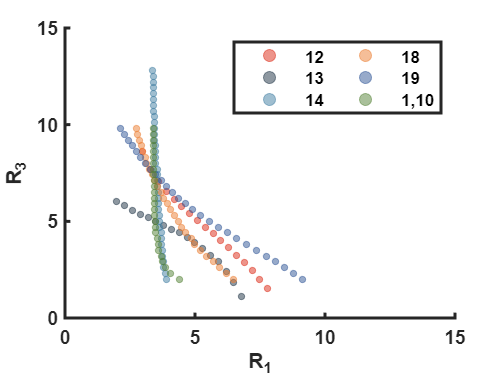


scatter(x8,y8,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,10')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end


